imgOG = imread("IMG_9269.jpg");
fprintf("Original Image:\n")

Original Image:


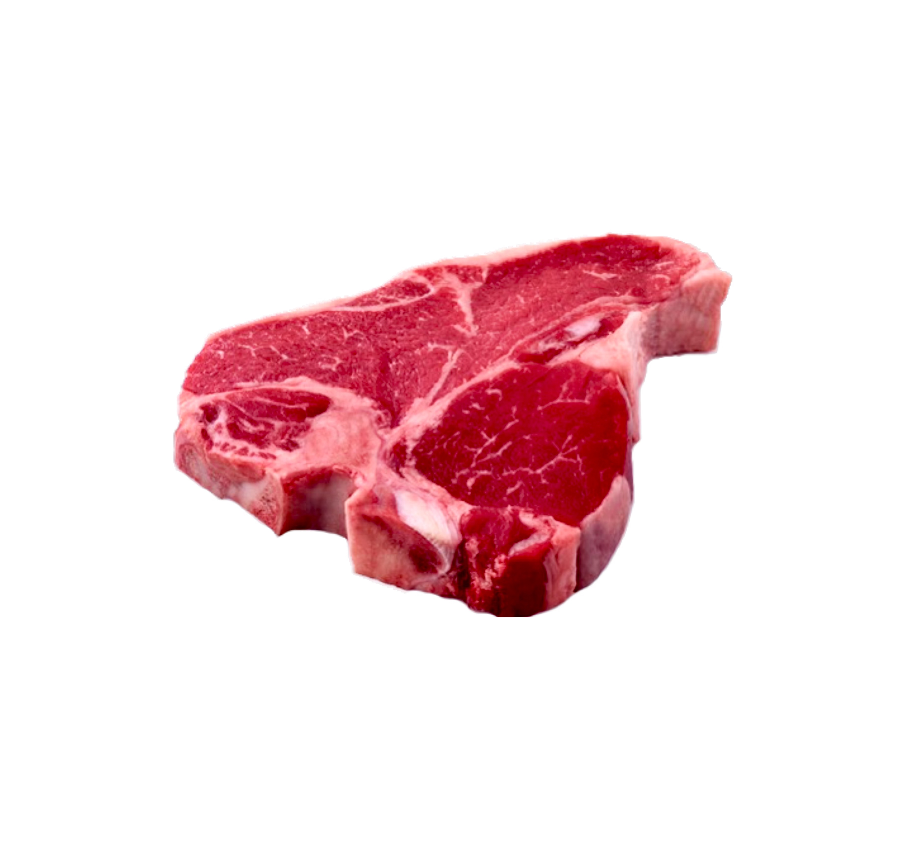

imshow(imgOG)

sizeOG = size(imgOG);
[n,d]=rat(sizeOG(2)/sizeOG(1),.05);
fprintf("Aspect Ratio For Original Image is %d:%d.\n", n,d)

Aspect Ratio For Original Image is 1:1.


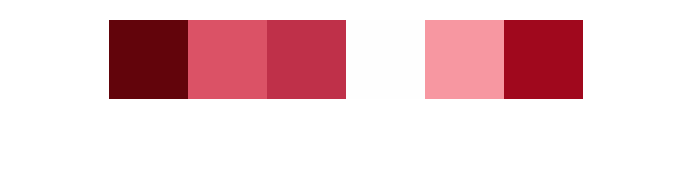

numClusters = 6;
[L, C] = imsegkmeans(imgOG,numClusters,"NumAttempts",6,"MaxIterations",200);
B = labeloverlay(imgOG,L);
pixels = [];
channelr = imgOG(:,:,1);
channelg = imgOG(:,:,2);
channelb = imgOG(:,:,3);
clust_map = zeros(numClusters,3);
for i = 1:numClusters
    logindex = (L == i);
    pixels = cat(3,pixels,logindex);
    filtered = [channelr(logindex) channelg(logindex) channelb(logindex)];
    avg = [mean(filtered(:,1)) mean(filtered(:,2)) mean(filtered(:,3))];
    clust_map(i,:) = avg/255;
end
imgColorKey  = 1:length(clust_map);
[ICK, mapck] = imresize(imgColorKey, clust_map, 80,"nearest"); 
imshow(ICK,clust_map)

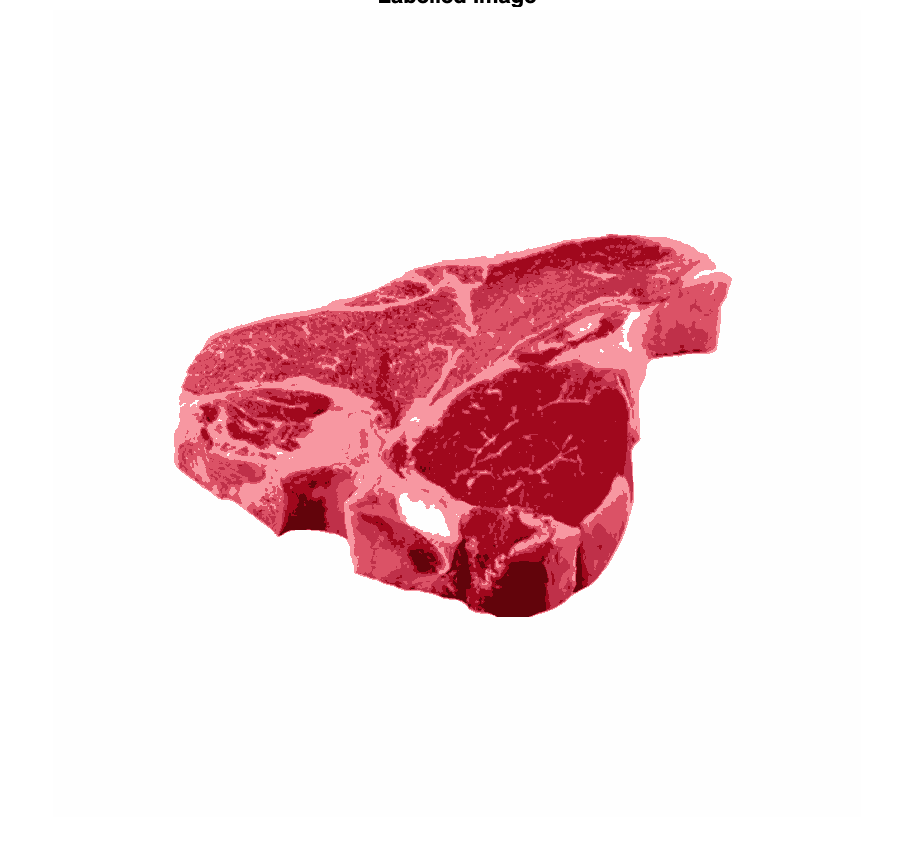

[imind,mapind] = rgb2ind(imgOG,clust_map,"nodither");
imshow(imind, mapind)
title("Labelled Image")